# **BUCLE FOR**

Los bucles (loops) se usan cuando se necesitan repetir un conjunto de instrucciones muchas veces. MATLAB soporta dos tipos diferentes de bucles: el bucle for y el bucle while.

Los bucles for son la opción más sencilla cuando usted sabe cuántas veces necesita repetir el bucle. Los bucles while son la opción más sencillas cuando necesia matener la repetición de las instrucciones hasta que se satisface un criterio.

Para los que tienen experiencia de programación previa, puede estar tentado a usar bucles de manera extensa, pero tenga presente que existen casos donde se puede omitir los bucles en MATLAB haciendo uso del comando **find **o mediante la **vectorización de código**, operando con vectores a la vez, en lugar de un elemento a la vez. **Evite los bucles siempre que sea posible, porque los programas resultantes corren más rápido y con frecuencia requieren menos pasos de programación**.

Estructura del ciclo for:

La primera linea identifica el bucle y define un indice, que es un número que cambia en cada paso a través del bucle. Después viene el grupo de comandos que se quiere ejecutar. Finalmente, la terminación del bucle con el comando **end.**

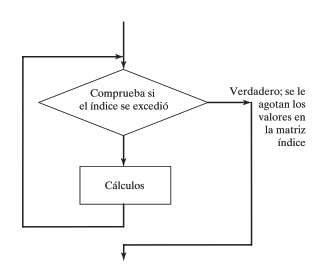

Uso de for con matriz

for k=[1 3 7]
    k
    
end 

k = 1

k = 3

k = 7

Ahora empleando matriz con índice definido con el operador dos puntos.

for k=1:5
    a=5^k
    
end

a = 5

a = 25

a = 125

a = 625

a = 3125

Definiendo una nueva matriz

a=zeros(1,5)

a =      0     0     0     0     0


for k=1:5
    a(k)=5^k
end

a =      5     0     0     0     0


a =      5    25     0     0     0


a =      5    25   125     0     0


a =      5    25   125   625     0


a =            5          25         125         625        3125


Sugerencia:

Es más fácil crear el vector **a **con el código:

k = 1:100,000

k =      1     2     3     4     5


% utilizar programación vectorial

a=5.^k

a =            5          25         125         625        3125


Ej. 2

Empleando la lista de califaciones, determinar ¿cuántos están por arriba de 90?

scores = [76, 45, 98, 97];
cont=0;
for k=1:length(scores)
       if scores(k)>90
           cont=cont+1
       end
end

cont = 1

cont = 2

scores = [76, 45, 98, 97];
cont=0;
for score=scores
       if score >90
           cont=cont+1
       end
end

cont = 1

cont = 2

% empleando programación vectorial
scores = [76, 45, 98, 97]

scores =     76    45    98    97


Index exceeds the number of array elements (4).

cont=0;


Ej. 3

Uso de lazos con matrices

for k= [1 2 3;1 4 9; 1 8 27]
    a=k'
end

a =      1     1     1


a =      2     4     8


a =      3     9    27


Usa toda una columna como el índice cada vez que pasa por el bucle. 